# 案例：用 Matlab 绘制高质量的论文插图 2

## 自定义颜色图

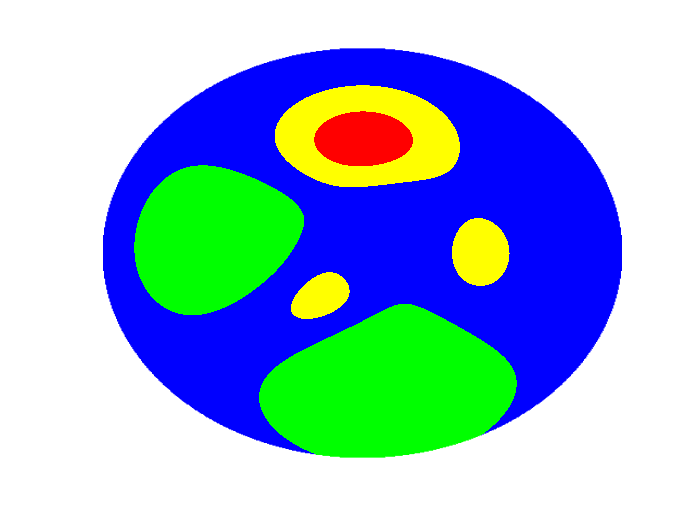

N = 500;
z = peaks(N);
% 选择 ROI 以外的不显示
for i = 1:N
    for j = 1:N
        if sqrt((i - N/2)*(i - N/2) + (j - N/2)*(j - N/2)) > 240
            z(i, j) = nan;
        end
    end
end
% 自定义颜色 大概就是给特定范围值指定颜色
N = 14 * 5;
crange = linspace(-6, 8, N);
cmap = zeros(N, 3);
for i = 1:N
    if crange(i) <= 0
        cmap(i, :) = [0, 1, 0];
    elseif crange(i) <= 3
        cmap(i, :) = [0, 0, 1];
    elseif crange(i) <= 6
        cmap(i, :) = [1, 1, 0];
    else
        cmap(i, :) = [1, 0, 0];
    end
end
surf(z)
colormap(cmap);
% 去网格
shading interp
% 视角
view(0, 90);
% 去坐标轴
axis off